% LQG For Linear Model
clc;
clear all;
close all;
[A,B,Q,R] = AB();
[C_1,C_3,C_4] = get_C_matrices();
D=0;
QXU = eye(7);
% Generate noise
w = wgn(6,1,5);
v = wgn(1,1,5);
QWV = [w;v]*[w' v'];
%Since we were asked to take only the smallest output vector, we use the
% C_1 which is having the lowest order in the observable states.
%Note that as the noise is white gaussian random noise, the output may
%change everytime we run the code.
LQG_state_space = lqg(ss(A,B,C_1,D),QXU,QWV)


LQG_state_space =
 
  A = 
             x1_e      x2_e      x3_e      x4_e      x5_e      x6_e
   x1_e    -2.549         1         0         0         0         0
   x2_e     -2.96    -0.049   -0.9785   0.07827   -0.9792   0.03919
   x3_e    0.5448         0         0         1         0         0
   x4_e   -0.7294  -0.00245   -0.5389  0.003913  -0.04896  0.001959
   x5_e     0.783         0         0         0         0         1
   x6_e   -0.5853   -0.0049  -0.09785  0.007827    -1.078  0.003919
 
  B = 
              y1
   x1_e    2.549
   x2_e    2.959
   x3_e  -0.5448
   x4_e   0.7293
   x5_e   -0.783
   x6_e   0.5852
 
  C = 
         x1_e    x2_e    x3_e    x4_e    x5_e    x6_e
   u1      -1     -49   1.532   78.27  0.7671   39.19
 
  D = 
       y1
   u1   0
 
Input groups:              
       Name        Channels
    Measurement       1    
                           
Output groups:          
      Name      Channels
    Controls       1    
                        
Continuo

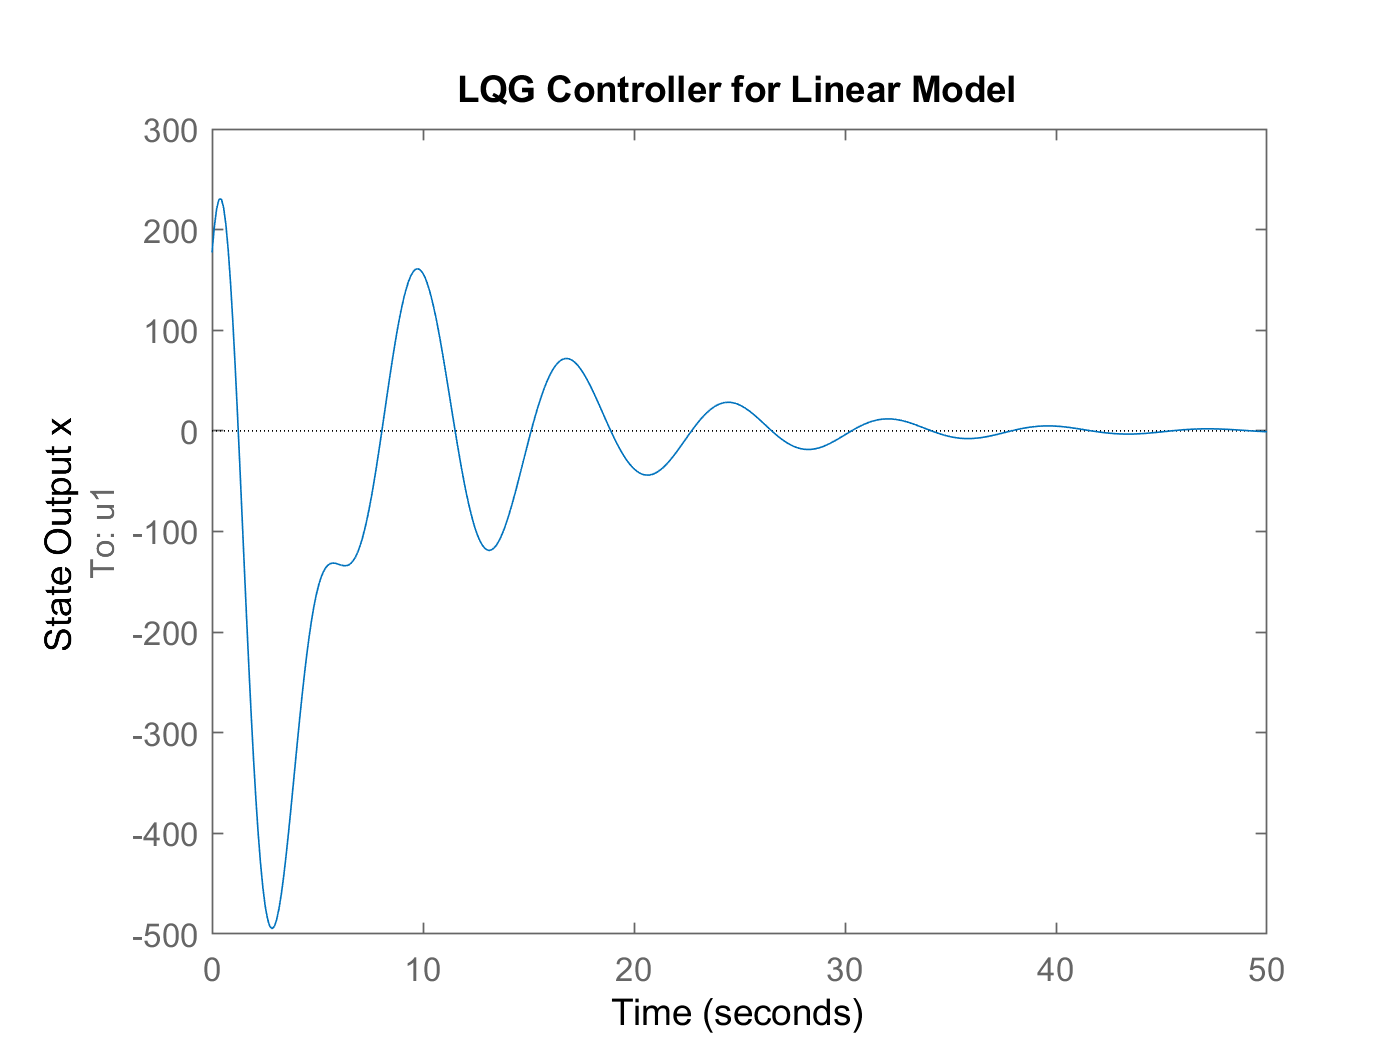

initial_state = [3,0.3,20,1,10,2];
figure
initial(LQG_state_space,initial_state)
title('LQG Controller for Linear Model')
xlabel('Time')
ylabel('State Output x')

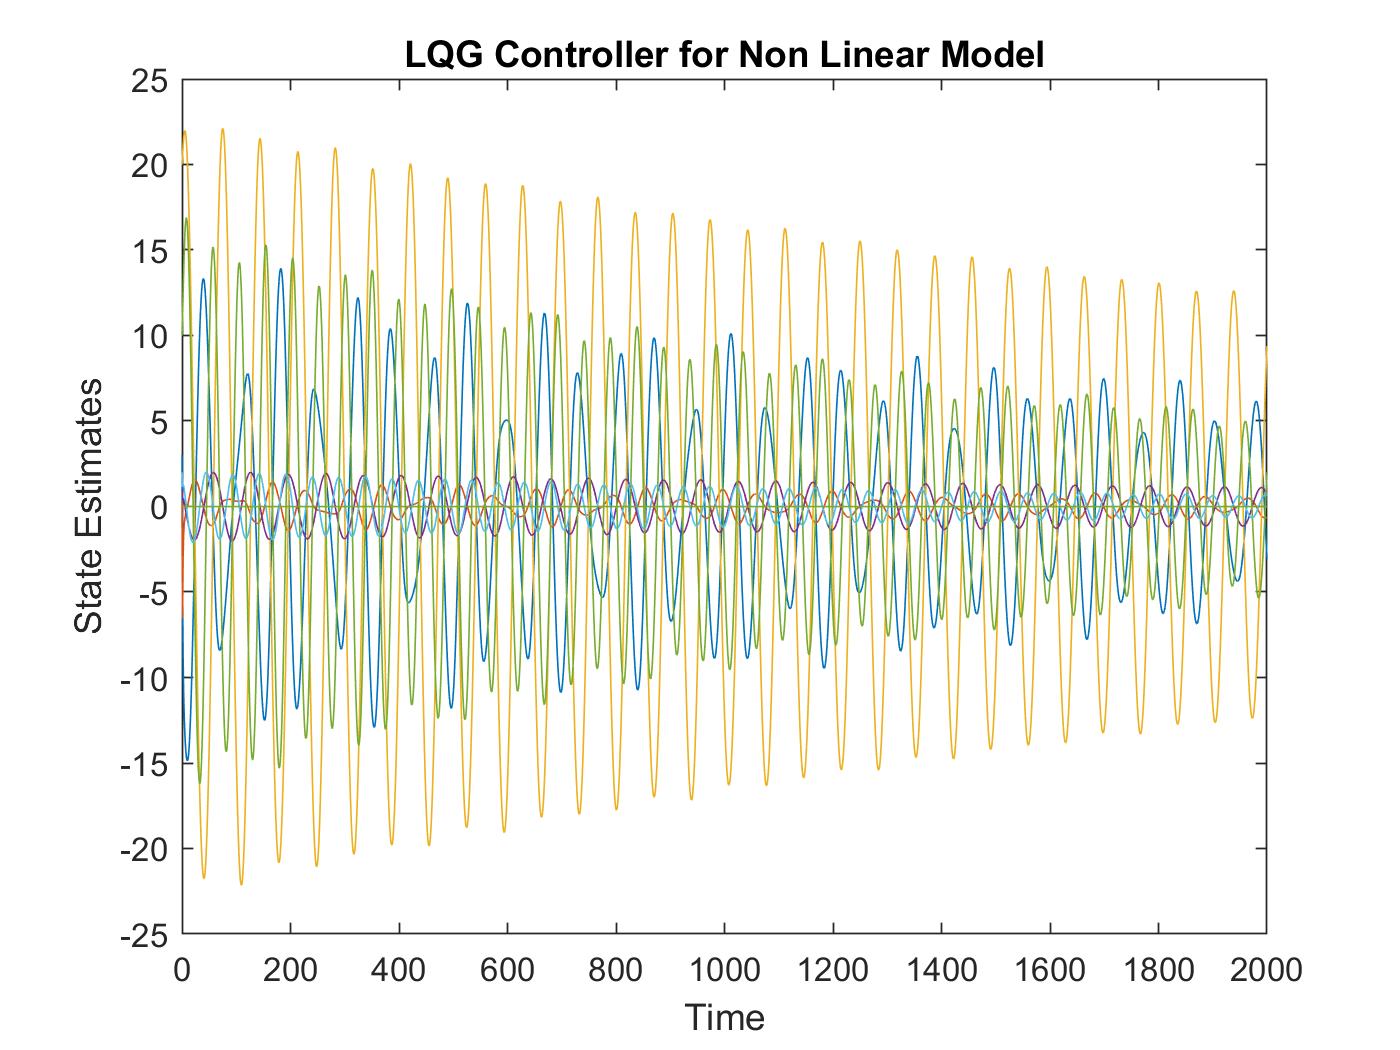

%Uncomment Below lines to get LQG controller for all states
% w = wgn(11,1,5);
% v = wgn(1,1,5);
% QWV = [w;v]*[w' v'];
% LQG_state_space = lqg(ss(A,B,eye(6),D),QXU,QWV)
% initial_state = [3,0.3,20,1,10,2];
% figure
% initial(LQG_state_space,initial_state)
% title('LQG Controller for Linear Model')
% xlabel('Time')
% ylabel('State Outputs')

%LQG (using kalman filter gain) for non-linear system model
initial_state = [3,0.3,20,1,10,2,0,0,0,0,0,0];
simulation_time = 0:1:2000;
[time,out] = ode45(@ode45_callback_lqg,simulation_time,initial_state);
figure
plot(time,out)
title('LQG Controller for Non Linear Model')
xlabel('Time')
ylabel('State Estimates')